close all;
clear all;
clc
%question 1
H = 3500;%max depth 3500m
zs = 0; %placement of sonar
dt = 0.005;
total_time = 30;
t = 0:dt:total_time;


theta01 = 90*pi/180;
theta02 = -2*pi/180;

x1 = zeros(size(t));
%x2 = zeros(size(t));

z1 = zeros(size(t));
%z2 = zeros(size(t));

theta1 = zeros(size(t));
%theta2 = zeros(size(t));

c1 = zeros(size(t));
%c2 = zeros(size(t));


x1(1) = 0;
%x2(1) = 0;

z1(1) = zs;
%z2(1) = zs;

theta1(1) = theta01;
%theta2(1) = theta02;

c1(1) = velocity(z1(1));
%c2(1) = velocity(z2(1));

snails_constant1 = cos(theta01)/c1(1);
%snails_constant2 = cos(theta02)/c2(1);

for i = 1:length(t)
    if i==1
        continue
    end
    
    
    
    x1(i) = x1(i-1) + c1(i-1)*dt*cos(theta1(i-1));
    z1(i) = z1(i-1) + c1(i-1)*dt*sin(theta1(i-1));
    c1(i) = velocity(z1(i));
    
    
    %x2(i) = x2(i-1) + c2(i-1)*dt*cos(theta2(i-1));
    %z2(i) = z2(i-1) + c2(i-1)*dt*sin(theta2(i-1));
    %c2(i) = velocity(z2(i));
    
    
    %snails_constant1 = cos(theta(i-1))/c(i-1);
    
    if snails_constant1*c1(i) <= 1
        theta1(i) = sign(theta1(i-1))*acos(snails_constant1*c1(i));
    else
        z1(i) =z1(i-1) ;
        c1(i) = c1(i-2);
        theta1(i) = -theta1(i-2);
        
    end
    
    %if snails_constant2*c2(i) <= 1
     %   theta2(i) = sign(theta2(i-1))*acos(snails_constant2*c2(i));
    %else
     %   z2(i) =z2(i-1) ;
      %  c2(i) = c2(i-2);
       % theta2(i) = -theta2(i-2);
        
    %end
    
    if z1(i) <= 0
        z1(i) =z1(i-1) ;
        c1(i) = c1(i-2);
        theta1(i) = -theta1(i-2);
        disp(t(i))
    elseif z1(i)>=H
        z1(i) =z1(i-1) ;
        c1(i) = c1(i-2);
        theta1(i) = -theta1(i-2);
        disp(t(i))
    end
    
%     if z2(i) < 0
%         z2(i) =z2(i-1) ;
%         c2(i) = c2(i-2);
%         theta2(i) = -theta2(i-2);
%     elseif z2(i)>H
%         z2(i) =z2(i-1) ;
%         c2(i) = c2(i-2);
%         theta2(i) = -theta2(i-2);
%     end
    
end

    2.4150



    4.8250



    7.2350



    9.6450



   12.0550



   14.4650



   16.8750



   19.2850



   21.6950



   24.1050



   26.5150



   28.9250



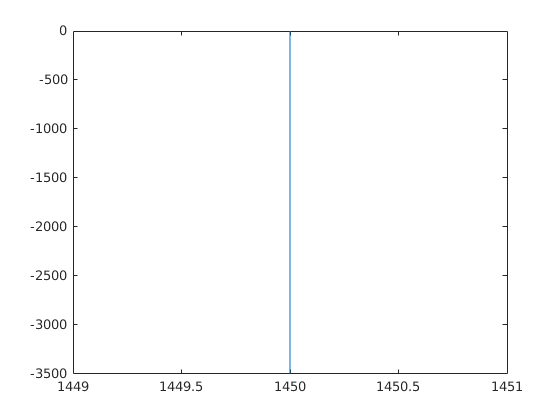



plot(c1,-z1)
hold on
%plot(c2,-z2)

hold off

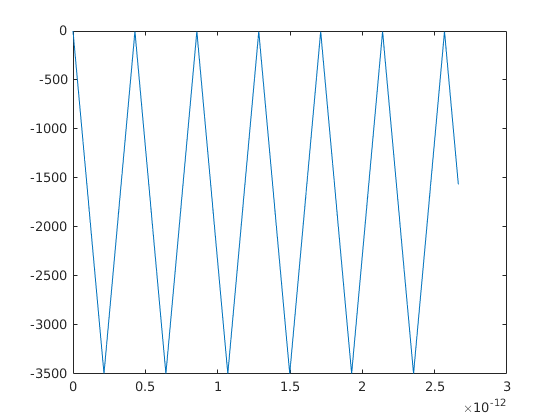

plot(x1,-z1)
hold on
%plot(x2,-z2)
hold off


disp('max_depth: ')

max_depth: 


disp(max(max([z1])))

   3.4945e+03



%question 1
H = 3500;%max depth 3500m
zs = 600; %placement of sonar
dt = 0.005;
total_time = 30;
t = 0:dt:total_time;


theta0 = [-2:0.1:2]*pi/180;
len_theta = length(theta0)

len_theta = 41

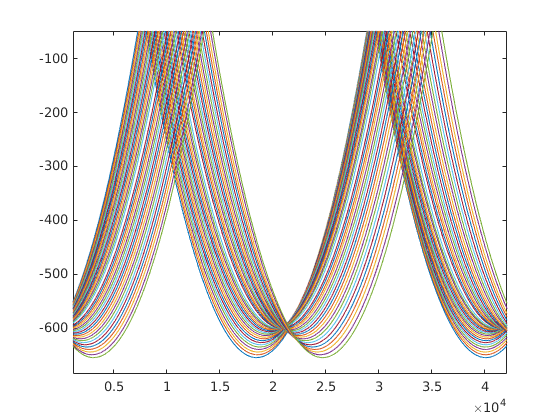

max_depth = 0;
for iii = theta0
    if iii==0
        continue
     
    end
    theta01 = iii;

x1 = zeros(size(t));

z1 = zeros(size(t));

theta1 = zeros(size(t));

c1 = zeros(size(t));


x1(1) = 0;

z1(1) = zs;

theta1(1) = theta01;

c1(1) = velocity(z1(1));

snails_constant1 = cos(theta01)/c1(1);
our_ans = 0;
for i = 1:length(t)
    if i==1
        continue
    end
    
    
    
    x1(i) = x1(i-1) + c1(i-1)*dt*cos(theta1(i-1));
    z1(i) = z1(i-1) + c1(i-1)*dt*sin(theta1(i-1));
    c1(i) = velocity(z1(i));

    %snails_constant1 = cos(theta(i-1))/c(i-1);
    
    if snails_constant1*c1(i) <= 1
        theta1(i) = sign(theta1(i-1))*acos(snails_constant1*c1(i));
    else
        z1(i) =z1(i-1) ;
        c1(i) = c1(i-2);
        theta1(i) = -theta1(i-2);
        
    end
    
    
    if z1(i) < 0
        z1(i) =z1(i-1) ;
        c1(i) = c1(i-2);
        theta1(i) = -theta1(i-2);
    elseif z1(i)>H
        z1(i) =z1(i-1) ;
        c1(i) = c1(i-2);
        theta1(i) = -theta1(i-2);
    end
    
    if max(max(z1))>max_depth
        max_depth = max(max(z1));
    end
    
end


plot(x1,-z1)
hold on
end    
hold off

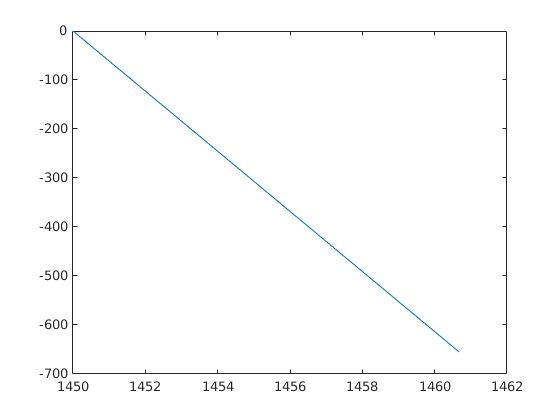

plot(c1,-z1)


ans = sprintf('max_depth: %f', max_depth);
disp(ans)

max_depth: 654.588861


for theta0 = 4.000000 and zs = 400, the max depth is 618.200570


for theta0 = 4.000000 and zs = 500, the max depth is 718.444759


for theta0 = 4.000000 and zs = 600, the max depth is 818.688949


for theta0 = 4.000000 and zs = 700, the max depth is 918.933138


for theta0 = 4.000000 and zs = 800, the max depth is 1019.177328


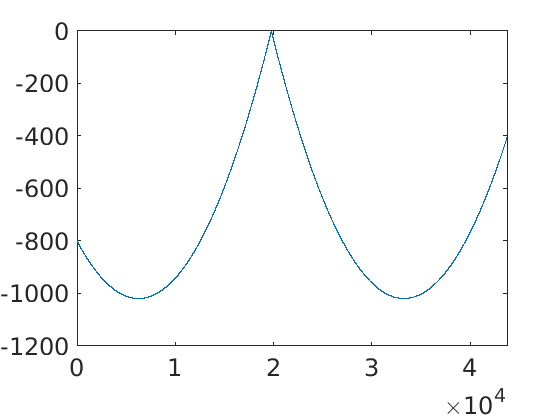

%question 2
clear all

H = 3500;%max depth 3500m

dt = 0.005;
total_time = 30;
t = 0:dt:total_time;

all_zs = [400,500,600,700,800]; %placement of sonar
all_theta01 = [4,5]*pi/180;

%calculating max depth for varrying zs
max_depth_wrt_zs = [];
for zs = all_zs
    
    x1 = zeros(size(t));
    
    z1 = zeros(size(t));
    
    theta1 = zeros(size(t));
    
    c1 = zeros(size(t));
    
    
    x1(1) = 0;
    
    z1(1) = zs;
    
    theta1(1) = all_theta01(1);
    
    c1(1) = velocity(z1(1));
    
    snails_constant1 = cos(theta1(1))/c1(1);
    
    for i = 1:length(t)
        if i==1
            continue
        end
        
        
        
        x1(i) = x1(i-1) + c1(i-1)*dt*cos(theta1(i-1));
        z1(i) = z1(i-1) + c1(i-1)*dt*sin(theta1(i-1));
        c1(i) = velocity(z1(i));
        
        %snails_constant1 = cos(theta(i-1))/c(i-1);
        
        if snails_constant1*c1(i) <= 1
            theta1(i) = sign(theta1(i-1))*acos(snails_constant1*c1(i));
        else
            z1(i) =z1(i-1) ;
            c1(i) = c1(i-2);
            theta1(i) = -theta1(i-2);
            
        end
        
        
        if z1(i) < 0
            z1(i) =z1(i-1) ;
            c1(i) = c1(i-2);
            theta1(i) = -theta1(i-2);
        elseif z1(i)>H
            z1(i) =z1(i-1) ;
            c1(i) = c1(i-2);
            theta1(i) = -theta1(i-2);
        end
        
        
    end
    max_depth_wrt_zs(end +1) = max(z1);
    
    ans = sprintf('for theta0 = %f and zs = %d, the max depth is %f',theta1(1)*180/pi,zs, max(z1));
    disp(ans)
    plot(x1, -z1)
end

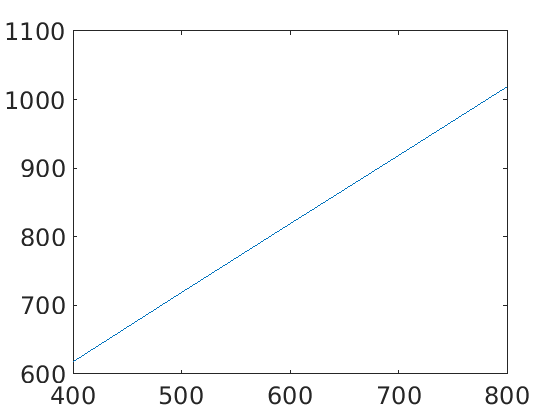

plot(all_zs, max_depth_wrt_zs)

    function c = velocity(z)
    c0 = 1450;
    gamma0 = 1.63*10^-2;
    c = c0 + gamma0*abs(z);
    c = c0;
    end